# `Fin Flutter Analysis`

### `Advanced Rocketry Club`

#### `Ryan Lemker`

`Based off apogee rocket report with slight equation corrections`

`Dennis J. Martin's bending-torsion flutter velocity (1958):`

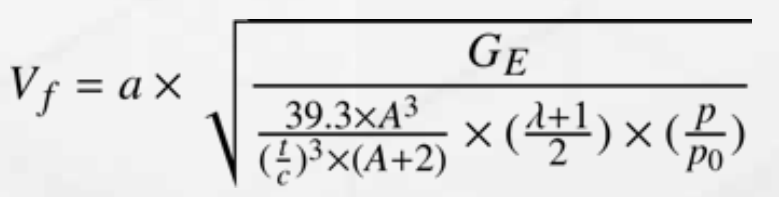

`[1] Bennett, J. K., 2023, “Fin Flutter Analysis Revisited (Again),” (615).  `[`Newsletter615.pdf (apogeerockets.com)`](https://www.apogeerockets.com/education/downloads/Newsletter615.pdf)    

[2] Sahr, J. D., 2016, “Trapezoidal Fin Flutter Analysis Revisited,” (411). [Newsletter411.pdf (apogeerockets.com)](https://www.apogeerockets.com/education/downloads/Newsletter411.pdf)

[3] Howard, Z., 2011, “How To Calculate Fin Flutter Speed,” (291).  [Newsletter291.indd (apogeerockets.com)](https://www.apogeerockets.com/education/downloads/Newsletter291.pdf)

## Input Data

Site Data:

clear all
V_max = 2162.119;%max predicted velocity, ft/s
A_max = 4576.512;%altitude of predicted max V, ft
% LSA = 4500;%launch site altitude (MSL), ft
% LST = 59;%temp at launch site (F). Can use standard 


Fin Geometry:

t = 0.375;%thickness, inches
m = 12.252;%sweep length, inches
L_c = 3;%tip chord length, inches
L_r = 16;%root chord, inches
height = 4.75;%semi span or height of body tube to tip, inches
G = 1200000;%shear modulus (double if tip to tip reinforcement [1]

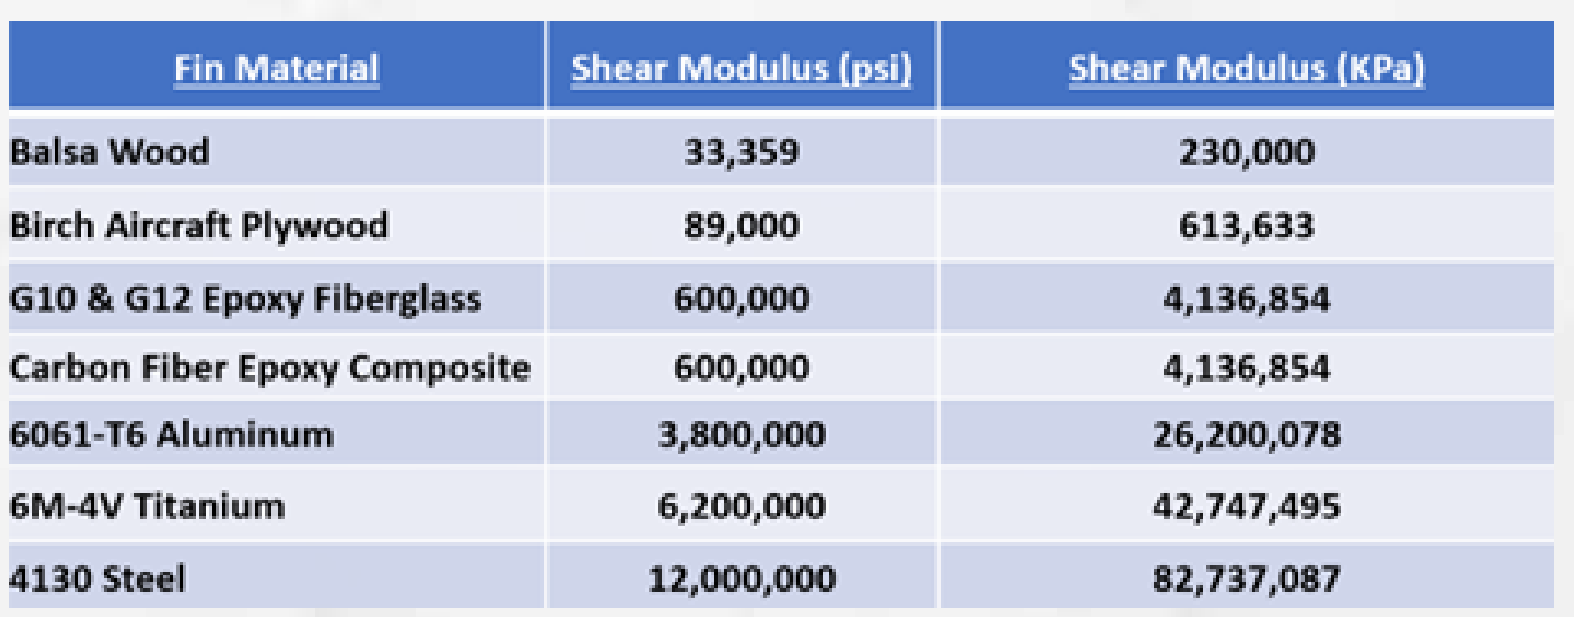

## Calculations

k = 1.4; %specific heat ratio
% R = 8.31432; %gas constant, Nm/mol*K
% M = 0.0289644; %molar mass air, kg/mol
p_o = 14.696; %standard psi at sea level
Cx = ((2*L_c*m)+L_c^2+(m*L_r)+(L_c*L_r)+L_r^2)/(3*(L_c+L_r));
%center of mass for trapezoidal fins
tc_ratio = t/L_r; %thickness ratio
lambda = L_c/L_r; %taper ratio
Area = height*(L_c+L_r)/2; %area, change for non-trapezoidal fins
A = (height^2)/Area; %aspect ratio
e = Cx/L_r-0.25; %epsilon,ԑ is a measure of distance expressed as a fraction of the whole root chord
DN = (24*e*k*p_o)/pi(); %denominator constant
Tf = 59-(0.00356*A_max); %temp at altitude
a = 49.03*sqrt(459.7+Tf); %speed of sound at altitude, m/s
p = 14.696*((Tf+459.7)/518.7)^5.256; %pressure at altitude, psi
% p_o*exp(-g*M*A_max/(R*Tf)) is another way, but must convert units
one = (DN*A^3)/((tc_ratio)^3*(A+2));
two = (lambda+1)/2;
three = p/p_o;
Vf = a*sqrt((G/(one*two*three)));
Vf_limit = Vf/1.25 %safety margin

Vf_limit =        2790.2


Safety_Margin_Percent = V_max/Vf_limit*100 %want less than 80% in general

Safety_Margin_Percent =        77.488
